T= readtable('South Africa Load data TN.xlsx',"VariableNamingRule", "preserve",'PreserveVariableNames',true);
T.Properties.VariableNames={'Date','Hour','Day','NettSentout'};

if ~isdatetime(T.Date)
    T.Date = datetime(T.Date, 'InputFormat', 'dd-MM-yyyy');
end

% Extract the year and week number from the Date column
T.Year = year(T.Date);
T.Week = week(T.Date);
T.Day = day(T.Date);
T.Month = month(T.Date);
T.Hour =hour(T.Date);


## Daily analysis

% Find the highest hourly total for each day in each month
highestHourlyDay = varfun(@max, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');

% Display the first few rows of the result to verify
disp(head(highestHourlyDay));

    Year    Month    Day    GroupCount    max_NettSentout
    ____    _____    ___    __________    _______________

    1988      1       1         24             14354     
    1988      1       2         24             14119     
    1988      1       3         24             13073     
    1988      1       4         24             15778     
    1988      1       5         24             16276     
    1988      1       6         24             16478     
    1988      1       7         24             16569     
    1988      1       8         24             16842     



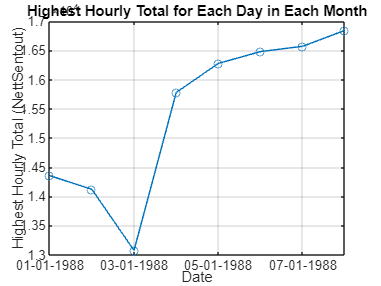

% Convert the year, month, and day columns back to a datetime array
highestHourlyDay.Date = datetime(highestHourlyDay.Year, highestHourlyDay.Month, highestHourlyDay.Day);

%Plot the highest hourly totals
figure;
plot(head(highestHourlyDay.Date), head(highestHourlyDay.max_NettSentout), '-o');
xlabel('Date');
ylabel('Highest Hourly Total (NettSentout)');
title('Highest Hourly Total for Each Day in Each Month');
grid on;
xtickformat('dd-MM-yyyy');

## Weekly analysis

%Find the highest hourly total for each week
highestHourlyWeek = varfun(@max, T,...
    'GroupingVariables', {'Year', 'Week'},...
    'InputVariables', 'NettSentout');

% Display the first few rows of the result to verify
disp(head(highestHourlyWeek));

    Year    Week    GroupCount    max_NettSentout
    ____    ____    __________    _______________

    1988     1          48             14354     
    1988     2         168             16842     
    1988     3         168             17574     
    1988     4         168             17516     
    1988     5         168             17628     
    1988     6         168             17795     
    1988     7         168             17944     
    1988     8         168             17970     



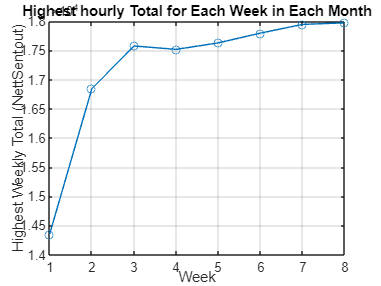



% Plot the graph for the highest hour in a week
figure;
plot(head(highestHourlyWeek.Week), head(highestHourlyWeek.max_NettSentout), '-o');
xlabel('Week');
ylabel('Highest Weekly Total (NettSentout)');
title('Highest hourly Total for Each Week in Each Month');
grid on;

## Monthly Analysis

peakMonthlyHours = varfun(@max, T, "GroupingVariables", {'Year', 'Month'}, InputVariables="NettSentout");

% Display few rows of the result
disp(head(peakMonthlyHours));

    Year    Month    GroupCount    max_NettSentout
    ____    _____    __________    _______________

    1988      1         744             17628     
    1988      2         696             17970     
    1988      3         744             18093     
    1988      4         720             18891     
    1988      5         744             19234     
    1988      6         720             20589     
    1988      7         744             20311     
    1988      8         744             19980     



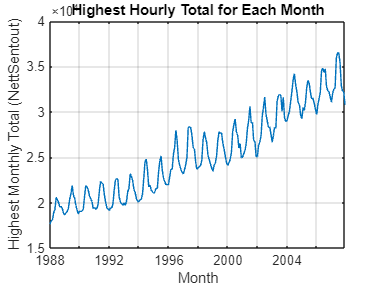

peakMonthlyHours.Date = datetime(peakMonthlyHours.Year, peakMonthlyHours.Month, 1);

% Plot the monthly peak load
figure;
plot(peakMonthlyHours.Date, peakMonthlyHours.max_NettSentout);
xlabel('Month');
ylabel('Highest Monthly Total (NettSentout)');
title('Highest Hourly Total for Each Month');
grid on;

## Yearly Analysis

% Find the peak load hours for each year
peakLoadHours = varfun(@max, T, ...
    'GroupingVariables', 'Year', ...
    'InputVariables', 'NettSentout');
[peakHourlyLoads, idxHours] = max(peakLoadHours.max_NettSentout);
peakLoadHoursDay = peakLoadHours(idxHours, :);

% Display the first few rows of the result
disp(head(peakLoadHours));

    Year    GroupCount    max_NettSentout
    ____    __________    _______________

    1988       8784            20589     
    1989       8760            21871     
    1990       8760            21863     
    1991       8760            22342     
    1992       8784            22640     
    1993       8760            23169     
    1994       8760            24798     
    1995       8760            25133     



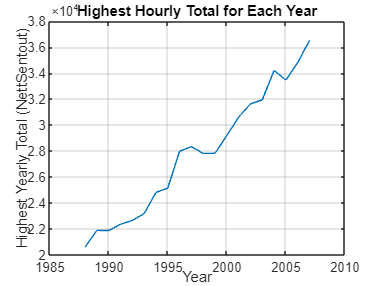

% Plot the yearly profiles
figure;
plot(peakLoadHours.Year, peakLoadHours.max_NettSentout);
xlabel('Year');
ylabel('Highest Yearly Total (NettSentout)');
title('Highest Hourly Total for Each Year');
grid on;

## Load Analysis